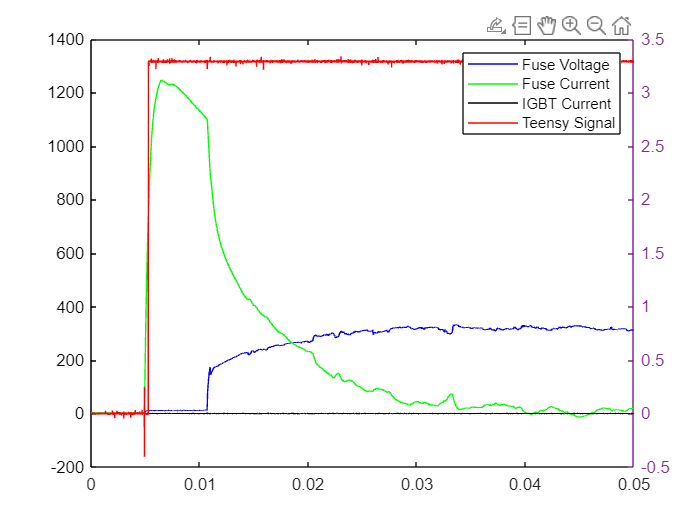

clear;clc;close all;

matFiles = load("20240424NO7.MAT");

FuseVolt = matFiles.CH01;
FuseCurr = matFiles.CH02;
IGBTCurr = matFiles.CH03;
TeensyOS = matFiles.CH04;

delta_T=1.0000e-06;

index1 = 1;
index2 =  length(FuseVolt);
index=0:index2-index1;

T0=delta_T*index;

plot(T0, FuseVolt,"b");hold on;
plot(T0, FuseCurr,"g");hold on;
plot(T0, IGBTCurr,"k");hold on;
yyaxis right;plot(T0, TeensyOS,"r");hold off;

legend('Fuse Voltage','Fuse Current','IGBT Current','Teensy Signal','Location','northeast')